close all;
clear;
load("C:\Users\lecci\Desktop\UNICT\Quarto Anno\Biomedical Systems\exercise\BCI_Project\s27.mat")
fs=eeg.srate;
ts=1/fs;
Ntrials=eeg.n_imagery_trials; %100 ma in realtà sono 100 per classe, quindi 200
trialsLeft=eeg.imagery_left(1:64,:)'; %CHANNELS FROM 1 TO 64 ARE FOR EEG
trialsRight=eeg.imagery_right(1:64,:)'; %FROM 64 TO 68 ARE FOR EMG (we don't need them)
Nevents=eeg.imagery_event; %sembrano tutti 0 ma ci sono 100 "1"
imagery_event_indices=find(Nevents==1);
%PRE PROCESSING
% Event_index=find(Nevents==1);
% LeftEvents=zeros(64,3*fs,100);
% RightEvents=zeros(64,3*fs,100);
% for i=1:length(Event_index)
%     LeftEvents(:,1+(i-1)*3*fs:3*fs*i)=trialsLeft(:,Event_index(i):(fs*3+Event_index(i))-1);%prendo tutti i 64 canali ma solo i 3 secondi dopo ogni "inizio motor imagery"
%     RightEvents(:,1+(i-1)*3*fs:3*fs*i)=trialsRight(:,Event_index(i):(fs*3+Event_index(i))-1);
% end




%EPOCHING
% epoch_lenght=3*fs;%Each epoch lasts 3 seconds
% %Epochs computation based on the current dataset
% num_epochs=Ntrials;
% %Preallocate matrices
% LeftSignal=zeros(size(LeftEvents,1), epoch_lenght,num_epochs);
% RightSignal=zeros(size(RightEvents,1), epoch_lenght,num_epochs);
% %Loop through each epoch and dividing data
% for i=1:num_epochs
%     start_idx=(i-1)*epoch_lenght+1;
%     end_idx=start_idx+epoch_lenght-1;
%     LeftSignal(:,:,i)=LeftEvents(:,start_idx:end_idx);
%     RightSignal(:,:,i)=RightEvents(:,start_idx:end_idx);
% end
%LeftSignal (also RightSignal) will be #channels x #epoch_samples x #epoch

%CHIEDI COME PRENDIAMO I NOSTRI MINUTI (48-49 per me) O SE
%SONO GIà ORDINATI PER MINUTI I DATASET




%Considerazioni:
%SMRs (sensorimotor rythms) desynchronize (decreases) with movement or motor imagery
%SMRs synchronizes (increases) in the postmovement period
%Relevant Rythms: µ-band (7-13 [Hz] quindi sarebbe alpha)and β-band (13-40 [Hz])

filtering

% %BUTTERWORTH ALPHA (7-13Hz)
% fc_low=7; %low cutoff frequency (Hz)
% fc_high=13; %high cutoff freq(Hz)
% order=5; %filter order (bigger orders->Unstable filter and wrong Frequency and Phase Responses)
% %calculate filter coefficients
% [b,a]=butter(order,[fc_low/(fs/2) fc_high/(fs/2)], 'bandpass');
% Left_Alpha_Filtered=filter(b,a,LeftSignal);
% Right_Alpha_Filtered=filter(b,a,RightSignal);
% LeftEvent_Alpha_Filtered=filter(b,a,LeftEvents);
% RightEvent_Alpha_Filtered=filter(b,a,RightEvents);
% 
% %Filter Control
% [H,f]=freqz(b,a,[],fs); 
% figure;
% subplot(2,1,1);
% plot(f,abs(H));
% xlabel('Frequency(Hz)');
% ylabel('Magnitude');
% title('Butterworth Alpha Bandpass Filter Frequency Response');
% xlim([0 100])
% %plot phase response
% subplot(2,1,2);
% plot(f,unwrap(angle(H)));
% xlabel('Frequency (Hz)');
% ylabel('Phase (rad)');
% title('Butterworth Alpha Bandpass Filter Phase Response'); %non lineare nelle fasi essendo un IIR
% xlim([0 100])
% figure
% zplane(b,a);
% 
% 
% %BUTTERWORTH BETA (13-40Hz)
% fc_low=13; %low cutoff frequency (Hz)
% fc_high=40; %high cutoff freq(Hz)
% order=8; %filter order (bigger orders->Unstable filter and wrong Frequency and Phase Responses)
% %calculate filter coefficients
% [b,a]=butter(order,[fc_low/(fs/2) fc_high/(fs/2)], 'bandpass');
% Left_Beta_Filtered=filter(b,a,LeftSignal);
% Right_Beta_Filtered=filter(b,a,RightSignal);
% LeftEvent_Beta_Filtered=filter(b,a,LeftEvents);
% RightEvent_Beta_Filtered=filter(b,a,RightEvents);
% 
% 
% %Filter Control
% [H,f]=freqz(b,a,[],fs); %[] serve a plottare il filtro come si deve
% figure;
% subplot(2,1,1);
% plot(f,abs(H));
% xlabel('Frequency(Hz)');
% ylabel('Magnitude');
% title('Butterworth Beta Bandpass Filter Frequency Response');
% xlim([0 100])
% %plot phase response
% subplot(2,1,2);
% plot(f,unwrap(angle(H)));
% xlabel('Frequency (Hz)');
% ylabel('Phase (rad)');
% title('Butterworth Beta Bandpass Filter Phase Response'); %non lineare nelle fasi essendo un IIR
% xlim([0 100])
% figure
% zplane(b,a);
% 

%NOTCH
%remove 60Hz with a notch filter
% f0 = 60; % Notch frequency (in Hz)
% BW = 0.1; % Desired 3dB bandwidth (in Hz)
% w0 = 2* pi* f0 / fs ;
% a = exp (- BW * w0/2) ; %parameter to change the bandwidth of the filter
% b = [1 -2*cos(w0) 1];
% a = [1 -2*a*cos(w0) a^2];
% [H,f]=freqz(b,a,[],fs); %[] serve a plottare il filtro come si deve
% figure;
% subplot(2,1,1);
% plot(f,abs(H));
% xlabel('Frequency(Hz)');
% ylabel('Magnitude');
% title('Notch Filter Frequency Response');
% xlim([0 100])
% %plot phase response
% subplot(2,1,2);
% plot(f,unwrap(angle(H)));
% xlabel('Frequency (Hz)');
% ylabel('Phase (rad)');
% title('Notch Filter Phase Response'); 
% xlim([0 100])

% 
% for i=1:64
%     Left_Alpha_Filtered(i,:,:)=filter(filter_Alpha,LeftSignal(i,:,:));
%     Left_Beta_Filtered(i,:,:)=filter(filter_Beta,LeftSignal(i,:,:));
%     LeftEvent_Alpha_Filtered(i,:)=filter(filter_Alpha,LeftEvents(i,:));
%     LeftEvent_Beta_Filtered(i,:)=filter(filter_Beta,LeftEvents(i,:));
% 
% 
%     Right_Alpha_Filtered(i,:,:)=filter(filter_Alpha,RightSignal(i,:,:));
%     Right_Beta_Filtered(i,:,:)=filter(filter_Beta,RightSignal(i,:,:));
%     RightEvent_Alpha_Filtered(i,:)=filter(filter_Alpha,RightEvents(i,:));
%     RightEvent_Beta_Filtered(i,:)=filter(filter_Beta,RightEvents(i,:));
% 
% end

%fl=7; fh=40; Beta waves and alpha waves all together
%left_imagery_detrend=detrend(trialsLeft);
%right_imagery_detrend=detrend(trialsRight);

filtered_left_imagery=filter(alphabeta_Filter,trialsLeft);
filtered_right_imagery=filter(alphabeta_Filter,trialsRight);

filtered_left_imagery_active=zeros((3*fs)*Ntrials,64);
filtered_right_imagery_active=zeros((3*fs)*Ntrials,64);
for i=1:Ntrials
    filtered_left_imagery_active(1+(i-1)*3*fs:i*3*fs,:)=filtered_left_imagery(imagery_event_indices(i):imagery_event_indices(i)+fs*3-1,:);
    filtered_right_imagery_active(1+(i-1)*3*fs:i*3*fs,:)=filtered_right_imagery(imagery_event_indices(i):imagery_event_indices(i)+fs*3-1,:);
end                 %CONFRONTA CON ALBERTOOOOOOOOOOOOOOOOOOOOOOOOOOOOOOO

epoching

left_dataset=zeros(3*fs,64,Ntrials);
right_dataset=zeros(3*fs,64,Ntrials);
%dataset=struct('data',cell(1,2*n_trials),'label',cell(1,2*n_trials));
%DA USARE PER TRAINING PHASE
for i=1:Ntrials
left_dataset(:,:,i)=filtered_left_imagery(imagery_event_indices(i):imagery_event_indices(i)+3*fs-1,:);
right_dataset(:,:,i)=filtered_right_imagery(imagery_event_indices(i):imagery_event_indices(i)+3*fs-1,:);
%right_dataset (also left_dataset) will be #samples x #channels x #epochs
%dataset(2*i-1).data=left_dataset(:,:,i);
%dataset(2*i-1).label='l';

%dataset(2*i).data=right_dataset(:,:,i);
%dataset(2*i).label='r';
end

%dataset_random=dataset(randperm(length(dataset)));    FONDAMENTALE NEL TRAINING

% percentage=0.75;
% n_train=round(2*n_trials*percentage);
% n_test=2*n_trials-n_train;

Working phase

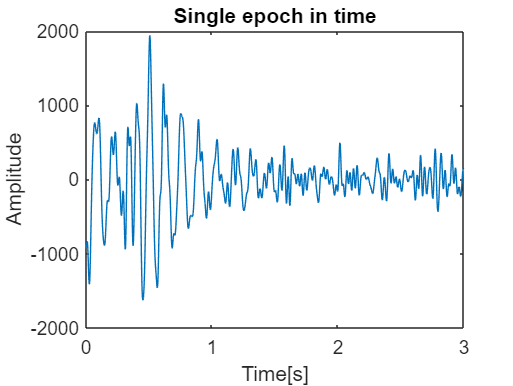

t=0:ts:(size(left_dataset,1)-1)*ts;
t_tot=0:ts:(size(filtered_right_imagery_active,1)-1)*ts;
%VEDI CHE DOPO FILTERING SEGNALI TUTTI A MEDIA NULLA XKE' HAI TOLTO LE
%BASSE FREQ E QUINDI I CONTRIBUTI COSTANTI
plot(t,right_dataset(:,1,1)) %primo canale prima epoca
xlabel('Time[s]')
ylabel('Amplitude')
title('Single epoch in time')

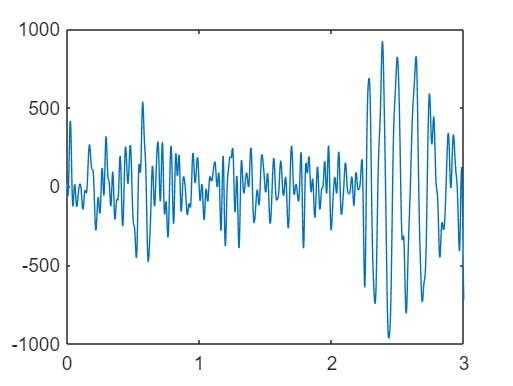

plot(t,right_dataset(:,1,2))%primo canale seconda epoca

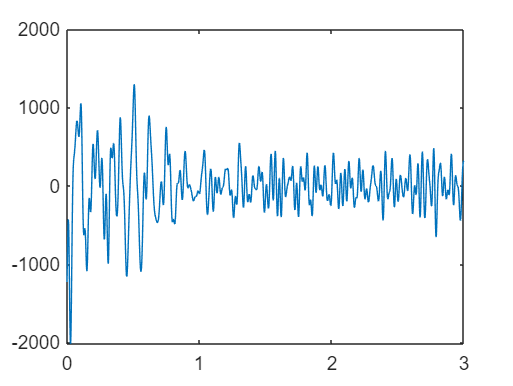

plot(t,right_dataset(:,2,1))%secondo canale prima epoca

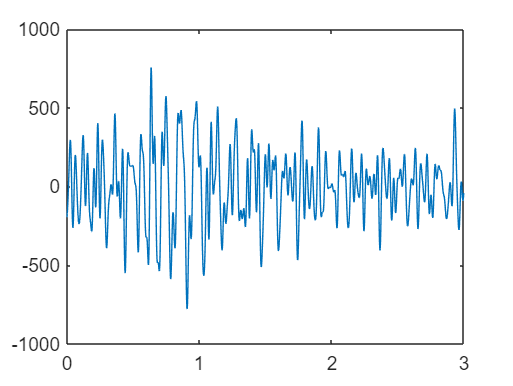

plot(t,right_dataset(:,2,3))%secondo canale seconda epoca

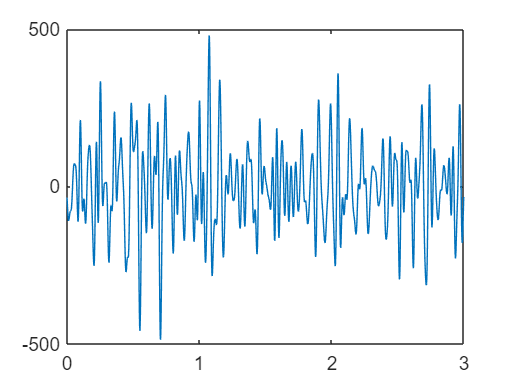

plot(t,right_dataset(:,50,25))

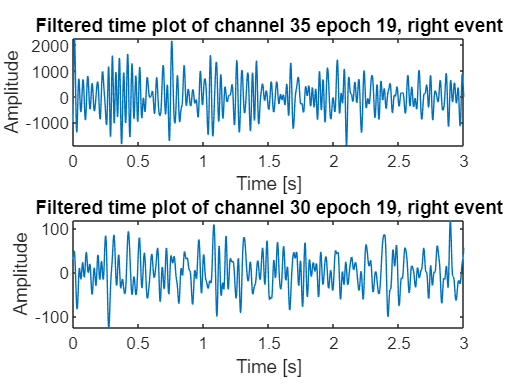


figure;
subplot(2,1,1)
plot(t,right_dataset(:,35,19))%dove c'è picco irregolare
title('Filtered time plot of channel 35 epoch 19, right event')
xlabel('Time [s]')
ylabel('Amplitude')

subplot(2,1,2)
plot(t,right_dataset(:,30,19))
title('Filtered time plot of channel 30 epoch 19, right event')
xlabel('Time [s]')
ylabel('Amplitude')

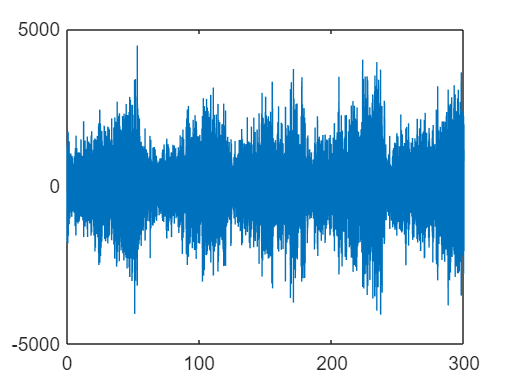



figure;
plot(t_tot,filtered_right_imagery_active(:,35))%canale 35 (energetico) tutte le epoche di movimenti right

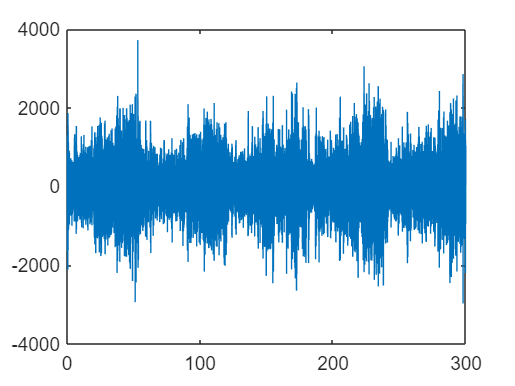

figure;
plot(t_tot,filtered_right_imagery_active(:,34))%canale 34 (energetico)tutte le epoche di movimenti right

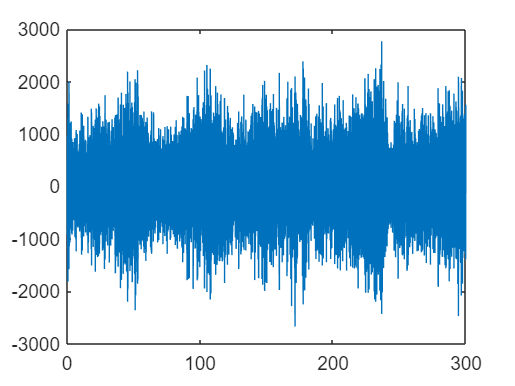

figure;
plot(t_tot,filtered_right_imagery_active(:,41))%canale 41 (poco energetico) tutte le epoche di movimenti left

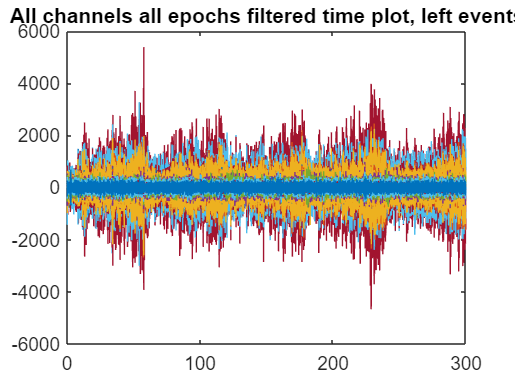



figure;
plot(t_tot,filtered_left_imagery_active(:,:))%tutti i canali, tutti i samples (non epoca, quindi 300secondi)
title('All channels all epochs filtered time plot, left events')

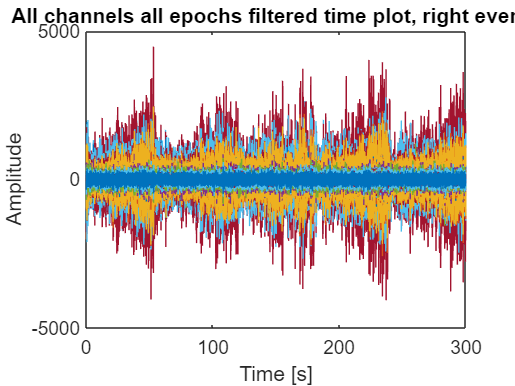

plot(t_tot,filtered_right_imagery_active(:,:))
title('All channels all epochs filtered time plot, right events')
xlabel('Time [s]')
ylabel('Amplitude')

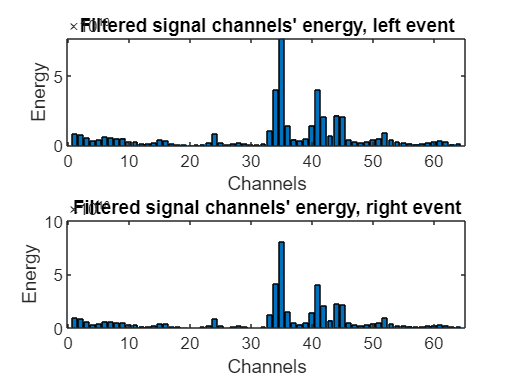

% %POSSIBILI ARTIFACT QUEI PICCHI SPARSI NEI GRAFICI SUBITO QUI SOPRA???????


for i=1:1:64
     [C]=xcorr(filtered_left_imagery_active(:,i));
     En(i)=max(C);
 end
figure;
subplot(2,1,1)
bar(En);
xlabel('Channels')
ylabel('Energy')
title("Filtered signal channels' energy, left event")
%35 34 e 41 sono i più energetici, 30 il meno energetico
for i=1:1:64
     [C]=xcorr(filtered_right_imagery_active(:,i));
     En(i)=max(C);
 end
subplot(2,1,2)
bar(En);  
xlabel('Channels')
ylabel('Energy')
title("Filtered signal channels' energy, right event")

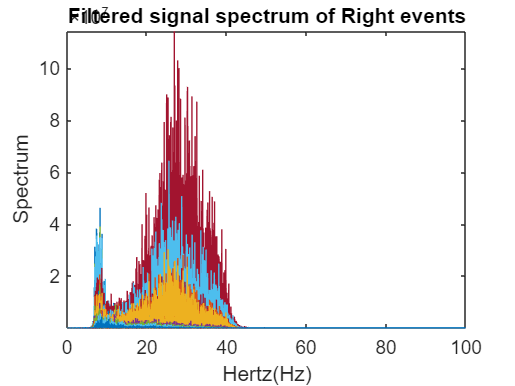


figure
[f,SP]=data_spectrum(filtered_right_imagery_active',fs,'e',1);
title('Filtered signal spectrum of Right events');
xlim([0 100])

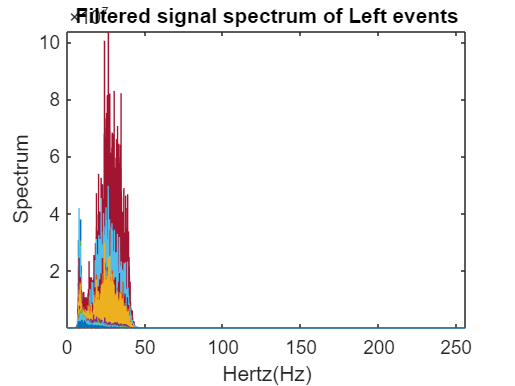

[f,SP]=data_spectrum(filtered_left_imagery_active',fs,'e',1);
title('Filtered signal spectrum of Left events');

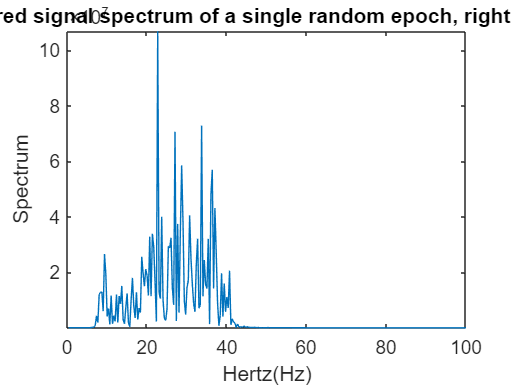



[f,SP]=data_spectrum(right_dataset(:,35,18)',fs,'e',1);
xlim([0 100])
title('Filtered signal spectrum of a single random epoch, right events');

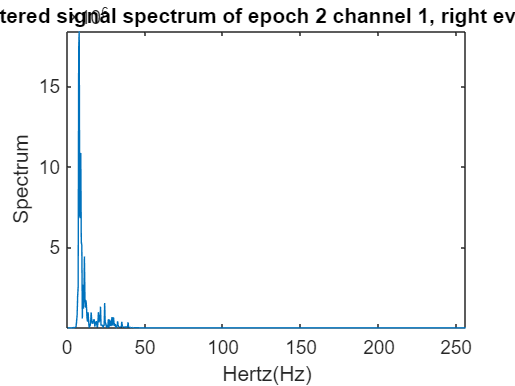

[f,SP]=data_spectrum(right_dataset(:,1,2)',fs,'e',1);
title('Filtered signal spectrum of epoch 2 channel 1, right events');

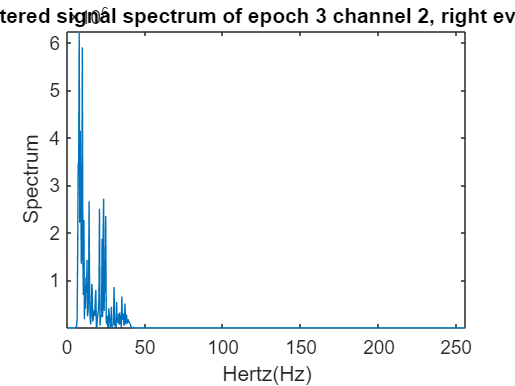

[f,SP]=data_spectrum(right_dataset(:,2,3)',fs,'e',1);
title('Filtered signal spectrum of epoch 3 channel 2, right events');



% [f,SP]=data_spectrum(LeftEvents,fs,'e',1);
% title('Original signal spectrum of Left events');
% [f,SP]=data_spectrum(RightEvents,fs,'e',1);          NON HO + I DATI EPOCATI MA NON FILTRATI XKE FACCIO PRIMA FILTERING POI EPOCHING
% title('Original signal spectrum of Right events');

% figure;
% subplot(3,1,1)
% plot(t_tot,RightEvent_Beta_Filtered(40,:))
% title('Beta filtered signal of channel 40, all epochs')
% xlabel('Time [s]')
% ylabel('Amplitude')
% 
% subplot(3,1,2)
% plot(t,Right_Beta_Filtered(40,:,19))
% title('Beta filtered signal of channel 40, 20th epoch')
% xlabel('Time [s]')
% ylabel('Amplitude')
% 
% subplot(3,1,3)
% plot(t,Right_Beta_Filtered(40,:,20))
% title('Beta filtered signal of channel 40, 21st epoch')
% xlabel('Time [s]')
% ylabel('Amplitude')